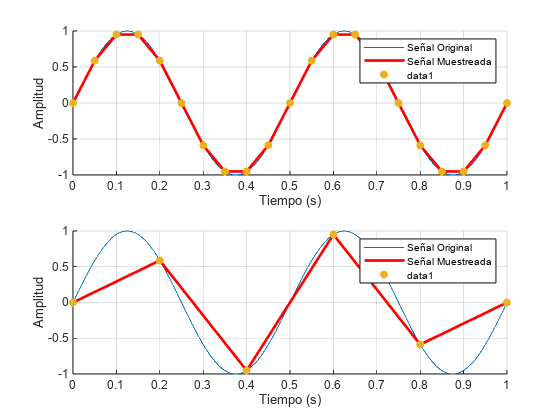

close all
clear all

% Frecuencia original deseada en Hz
frecuencia_original = 2; % Por ejemplo, una frecuencia de 2 Hz

% Amplitud y fase (opcional)
amplitud = 1;
fase = 0;

% Tiempo
periodo_original = 1 / frecuencia_original; % Período de la señal original
t = 0:0.001:1; % Vector de tiempo de 0 a 1 segundo con un paso de 0.001 segundos

% Crear la señal senoidal con la frecuencia original
senal_seno_original = amplitud * sin(2 * pi * frecuencia_original * t + fase);

% Muestrear la señal con un tren de deltas de frecuencia de 15 Hz
frecuencia_muestreo1 = 20; % Frecuencia de muestreo de 15 Hz
paso_tiempo_muestreo = 1 / frecuencia_muestreo1; % Período de muestreo de 0.067 segundos
t_muestreo = 0:paso_tiempo_muestreo:1; % Vector de tiempo de muestreo

% Evaluar la señal en los momentos de muestreo
senal_muestreada = amplitud * sin(2 * pi * frecuencia_original * t_muestreo + fase);

% Graficar la señal original y la señal muestreada uniendo los puntos
figure
subplot(2,1,1)
hold on
plot(t, senal_seno_original, 'DisplayName', 'Señal Original');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

plot(t_muestreo, senal_muestreada, 'r', 'LineWidth', 2, 'DisplayName', 'Señal Muestreada');
scatter(t_muestreo, senal_muestreada, 'filled');

hold off; 
xlabel('Tiempo (s)');
ylabel('Amplitud');

grid on;

% Agregar una leyenda
legend;;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frecuencia original deseada en Hz
frecuencia_original = 2; % Por ejemplo, una frecuencia de 2 Hz

% Amplitud y fase (opcional)
amplitud = 1;
fase = 0;

% Tiempo
periodo_original = 1 / frecuencia_original; % Período de la señal original
t = 0:0.001:1; % Vector de tiempo de 0 a 1 segundo con un paso de 0.001 segundos

% Crear la señal senoidal con la frecuencia original
senal_seno_original = amplitud * sin(2 * pi * frecuencia_original * t + fase);

% Muestrear la señal con un tren de deltas de frecuencia de 15 Hz
frecuencia_muestreo2 = 5; % Frecuencia de muestreo de 15 Hz
paso_tiempo_muestreo = 1 / frecuencia_muestreo2; % Período de muestreo de 0.067 segundos
t_muestreo = 0:paso_tiempo_muestreo:1; % Vector de tiempo de muestreo

% Evaluar la señal en los momentos de muestreo
senal_muestreada = amplitud * sin(2 * pi * frecuencia_original * t_muestreo + fase);

% Graficar la señal original y la señal muestreada uniendo los puntos
subplot(2,1,2)
hold on

plot(t, senal_seno_original, 'DisplayName', 'Señal Original');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

plot(t_muestreo, senal_muestreada, 'r', 'LineWidth', 2, 'DisplayName', 'Señal Muestreada');
scatter(t_muestreo, senal_muestreada, 'filled');

hold off; 
xlabel('Tiempo (s)');
ylabel('Amplitud');

grid on;

% Agregar una leyenda
legend;;